We want to evaluate the following function


$$y(t) = 1 - \frac{e^{-0.3(2)t}}{\sqrt{1 - 0.3^2}} 
        \sin\!\left(2\sqrt{1 - 0.3^2}\,t + 
        \tan^{-1}\!\frac{\sqrt{1 - 0.3^2}}{0.3}\right)$$


for a number of values of time between 0-10 s.

Create a vector of length `N` with time values between 0-10 s.

tt = linspace(0,10,25);

Then evaluate the function for each element in `tt` and store the results in a new vector called `yy`.

zeta = 0.3;
wn = 2;
wd = wn*sqrt(1 - zeta^2);
phi = atan(sqrt(1 - zeta^2)/zeta);
yy = 1 - exp(-zeta*wn*tt)./sqrt(1 - zeta^2)...
    .*sin(wd*tt + phi);


To visualize the function, plot the `N` descrete points.

figure(1);
clf()
plot(tt, yy, '-o', 'LineWidth', 1.5)
xlabel('Time (s)')
ylabel('Response y(t)')
title('Time Response')
grid on

### Find all the interval of time for which $y(t) \geq 1.2$

First, we can use comparison opperators to do element-wise comparison.  This command will generate a vector that is the same length as `tt`, but where each element is the result of the comparison:

comparison_vector = (yy >= 1.2)

comparison_vector = 1×25 logical array
   0   0   0   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


Next we can find the indices of that comparison vector that are true (1).  This command returns a vector of all the indices for which the comparison is true.

indices = find(yy >= 1.2)

indices =      4     5     6


Because the vectors `tt` and `yy` contain corresponding elements, we can use the indices to find the times that correspond to the comparison:

fprintf("From t = %4.2f to %4.2f, the values of y(t) are >= 1.2 \n", ...
    tt(indices(1)), tt(indices(end)));

From t = 1.25 to 2.08, the values of y(t) are >= 1.2 


We can then add new markers to only that subset of the vectors...

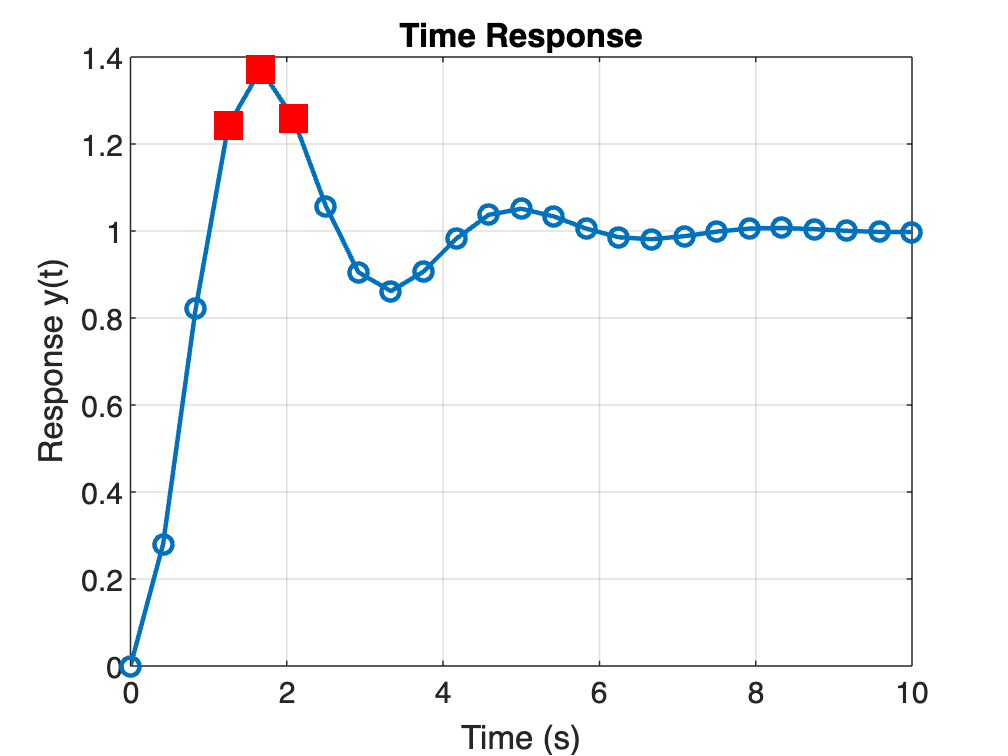

hold on
plot(tt(indices), yy(indices), 'rs', 'MarkerSize', 12, 'MarkerFaceColor', 'r')